$$\mathbf x,\, \mathbf P$$ are the state mean and covariance. They correspond to $$x$$ and $$\sigma^2$$.

$$\mathbf F$$ is the state transition function. When multiplied by $\bf x$ it computes the prior.

bar = prior

not bar = posterior

## Prediction step

mean:                   $\bar{\mathbf{x}}=\mathbf{F}\mathbf{x}+\mathbf{B}\mathbf{u}$

covariance:         $\bar{\mathbf{P}}=\mathbf{F}\mathbf{P}\mathbf{F}+\mathbf{Q}$

## Update step

residual:               $\mathbf{e}=\mathbf{z}-\mathbf{H}\bar{\mathbf{x}}$

gain:                       $\mathbf{K}=\bar{\mathbf{P}}\mathbf{H}^T(\mathbf{H}\bar{\mathbf{P}}\mathbf{H}^T+\mathbf{R})^{-1}$

mean:                   $\mathbf{x}=\bar{\mathbf{x}}+\mathbf{K}\mathbf{e}$

covariance:         $\mathbf{P}=(\mathbf{I}-\mathbf{K}\mathbf{H})\bar{\mathbf{P}}$

### **Clearing**

clear variables; close all; clc;
addpath('../utilities');

### **Model**

% number of states, solitamente n
dim_x = 2;

% number of measures (sensors), solitamente m
dim_z = 1;

% number of control input, solitamente p
dim_u = 1;

% discrete time step
dt = 0.1;

% state matrix
% Newton equations of motion
F = [1 dt; 0 1];

% measurement matrix
H = [1 0];

% control input matrix
B = zeros(dim_x, dim_u);

% process noise covariance matrix
% Q = [0.588 1.175; 1.175 2.35];
Q = diag([1e-5 1e-5]);

% measurement noise covariance matrix
R = 5;

% control input
u = 0;

### **Initial conditions**

% initial state (mean)
x0 = [10 0]';

% initial belief of the state (covariance)
P0 = diag([500 500]);

### **Filter settings**

% number of iterations
iterations = 500;

% preallocate memory
x_posterior = cell(1, iterations);
P_posterior = cell(1, iterations);
x_prior = cell(1, iterations);
P_prior = cell(1, iterations);
residuals = cell(1, iterations);
gains = cell(1, iterations);

### **Compute data**

[true_values, measures] = compute_dog_data(R, Q, iterations, dt);

### **Filter initialization**

% 1. Initialize the state of the filter
x = x0;

% 2. Initialize our belief in the state
P = P0;

### **Filtering**

for tt = 1:iterations
    % predict step:
    % 1. Use process model to predict state at the next time step (what we expect) 
    x = F*x + B*u;
    % 2. Adjust belief to account for the uncertainty in prediction   
    P = F*P*F' + Q;
    
    % saving
    x_prior{tt} = x;
    P_prior{tt} = P;
   
    % update step:
    % 1. Get a measurement and associated belief about its accuracy
    z = measures{tt};
    % 2. Compute residual between estimated state and measurement
    e = z - H*x;
    % 3. Compute scaling factor based on whether the measurement or prediction is more accurate
    K = P*H' / (H*P*H' + R);
    % 4. set state between the prediction and measurement based on scaling factor
    x = x + K*e;
    % 5. update belief in the state based on how certain we are in the measurement
    % P = P - K*H*P;
    % Joseph equation to reduce numeric errors
    P = (eye(dim_x)-K*H)*P*(eye(dim_x)-K*H)' + K*R*K';
    
    % saving
    x_posterior{tt} = x;
    P_posterior{tt} = P;
    gains{tt} = K;
    residuals{tt} = e;
end

### **Plot**

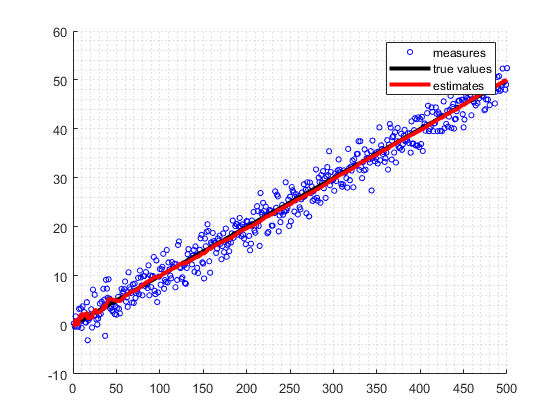

x_m = cell2mat(x_posterior);
z_m = cell2mat(measures);
true_values_m = cell2mat(true_values);

figure; hold on; grid minor;
for tt = 1 : dim_z
    plot(z_m(tt,:), 'bo', 'MarkerSize', 4)
    plot(true_values_m(tt,:), 'k', 'LineWidth', 3)
    plot(x_m(tt,:), 'r', 'LineWidth', 3)
end
legend('measures', 'true values', 'estimates')

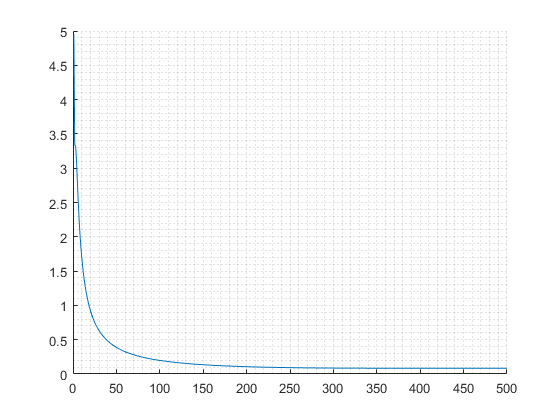

P_posterior_m = cell2mat(P_posterior);

figure; hold on; grid minor;
plot(P_posterior_m(1, 1:2:end))

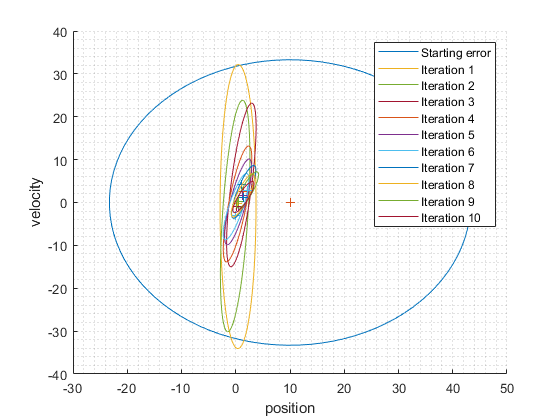

figure; hold on; grid minor;
h = plot_covariance_ellipse(x0, P0, 0.67);
h.set('DisplayName', 'Starting error');
xlabel('position'); ylabel('velocity'); legend('show');
for tt = 1 : 1 : 10
    h = plot_covariance_ellipse(x_m(:, tt), P_posterior_m(:, 2*tt-1:2*tt), 0.67);
    h.set('DisplayName', ['Iteration ' num2str(tt)]);
end

### **Residuals**

e_m = cell2mat(residuals);
mean(e_m)

ans = 0.0423

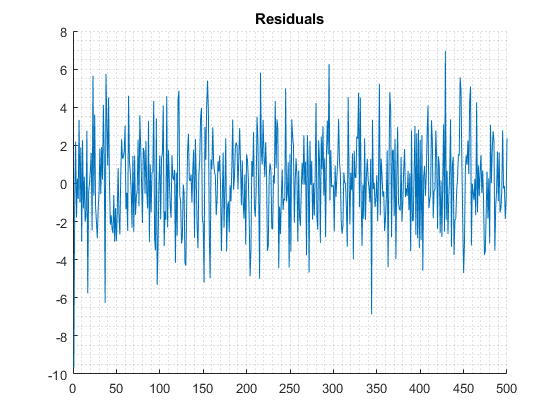

figure; hold on; grid minor;
plot(e_m)
title('Residuals')

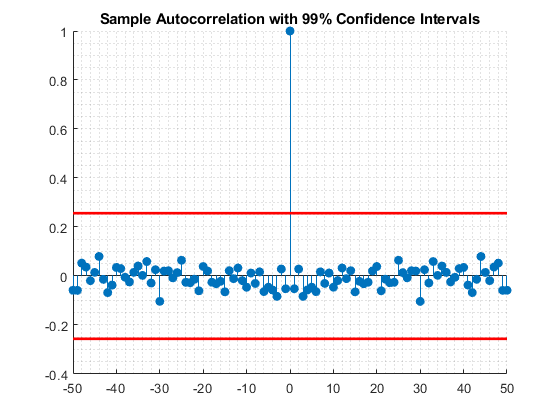


[xc, lags] = xcorr(e_m, 50, 'coeff');
conf99 = sqrt(2) * erfcinv(2*.01/2);
lconf = -conf99/sqrt(length(xc));
upconf = conf99/sqrt(length(xc));
figure; hold on; grid minor;
stem(lags, xc, 'filled')
plot(lags, lconf*ones(size(lags)), 'r', 'LineWidth', 2)
plot(lags, upconf*ones(size(lags)), 'r', 'LineWidth', 2)
title('Sample Autocorrelation with 99% Confidence Intervals')

% matlab kalman filter function
D = 0;
G = eye(2);
V = [0, 0];
sys = ss(F, [B, G], H, [D, V], dt);
[KEST, L, P] = kalman(sys, Q, R);